依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Similar activity in MOp Learned_task_A and Transfer_task_B

预加载此脚本一次即可

TransferLearning.FullCalciumPreload;

不能按照达峰时间排序

MOpAuc=MOpNtats;
MOpAuc.NTATS=MOpAuc.NTATS(:,:,["Naive_cue1_water","Learned4_cue1_water","Transfer_cue2_water_hit","Transfer_cue2_water_miss"]);
MOpAuc=UniExp.HeatmapSort(MOpAuc,UniExp.Flags.Mean);

行为曲线

[BehaviorTags,Min,Max]=structfun(@(T)TransferLearning.CollectBehaviorTags(T,width(MOpAuc.NTATS)),DataSet.TableQuery(["Mouse","NormalizedTags"],UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig1E')),UniformOutput=false);
Min=struct2cell(Min);
Min=min([Min{:}]);
Max=struct2cell(Max);
Max=max([Max{:}]);

[ProbabilityMean,ProbabilitySem]=structfun(@(T)TransferLearning.BehaviorTagToProbability(T,Min,Max),BehaviorTags,UniformOutput=false);
ProbabilityMean=[ProbabilityMean.Naive_task_A;ProbabilityMean.Learned_task_A;ProbabilityMean.Transfer_task_B_hit;ProbabilityMean.Transfer_task_B_miss];
ProbabilitySem=[ProbabilitySem.Naive_task_A;ProbabilitySem.Learned_task_A;ProbabilitySem.Transfer_task_B_hit;ProbabilitySem.Transfer_task_B_miss];

Colors=GlobalOptimization.ColorAllocate(4,[1,1,1]);

GlobalSearch stopped because it analyzed all the trial points.

All 57 local solver runs converged with a positive local solver exit flag.


Xs=linspace(-3,12,size(ProbabilityMean,2))';

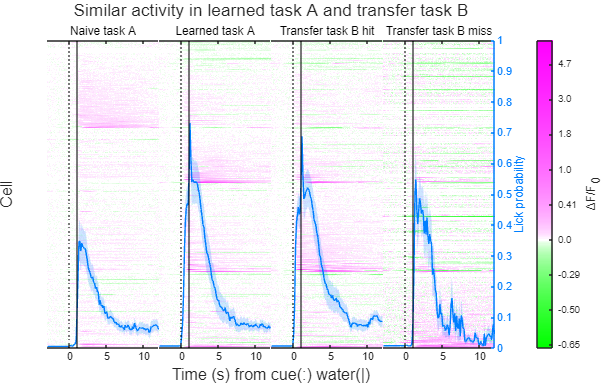

Fig=figure;
Layout=tiledlayout(1,4,TileSpacing='none',Padding='tight');
[~,Axes]=UniExp.LanearHeatmap(MOpAuc.NTATS,UniExp.Flags.HideYAxis,UniExp.Flags.ScaleColor,Layout=Layout,ImagescStyle={'XData',[-3,12]},SubTitles=["Naive task A","Learned task A","Transfer task B hit","Transfer task B miss"],LMHColor=[Colors(4,:);1,1,1;Colors(2,:)]);
for A=1:numel(Axes)
	Ax=Axes(A);
	yyaxis(Ax,'right');
	ylim(Ax,[0,1]);
	Ax.YAxis(2).Visible=false;
	MATLAB.Graphics.MultiShadowedLines(ProbabilityMean(A,:)',ProbabilitySem(A,:)',X=Xs,EdgeColors=Colors(3,:),Ax=Ax);
	xline(Ax,0,':',Color=Colors(1,:));
	xline(Ax,1,Color=Colors(1,:));
end
Ax.YAxis(2).Color=Colors(3,:);
Ax.YAxis(2).Visible=true;
ylabel(Ax,'Lick probability');
ylabel(Layout,'Cell');
xlabel(Layout,'Time (s) from cue(:) water(|)');
CB=colorbar;
CB.Label.String='ΔF/F_0';
title(Layout,'Similar activity in learned task A and transfer task B');
MATLAB.Graphics.FigureAspectRatio(8,5,1);
CB.TickLabels=MATLAB.SignificantFixedpoint(2.^str2double(CB.TickLabels)-1,2);
print(TransferLearning.ProjectPath('Fig1E.svg'),'-dsvg');